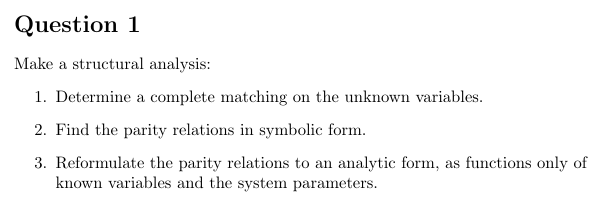

clear all;
close all;
clc;
load('ECP_values.mat');
% Physical system parameters
J_1 = ECP_values(1);            % Disk 1 inertia kgm^2
J_2 = ECP_values(2);            % Disk 2 inertia kgm^2
J_3 = ECP_values(3);            % Disk 3 inertia kgm^2
k_1 = ECP_values(4);            % Shaft 1-2 stiffness Nm/rad
k_2 = ECP_values(5);            % Shaft 2-3 stiffness Nm/rad
b_1 = mean(ECP_values([6 7]));  % Disk 1 damping and friction Nms/rad
b_2 = mean(ECP_values([8 9]));  % Disk 2 damping and friction Nms/rad
b_3 = mean(ECP_values([10 11]));% Disk 3 damping and friction Nms/rad
T_Cp = ECP_values(12);          % Disk 1 Coulomb friction in positive direction
T_Cm = ECP_values(13);          % Disk 1 Coulomb friction in negative direction
atan_scale = 100;               % Sign approximation factor
w_th = 0.75;                    % Threshold angular velocity rad/s

% The system states are [theta_1;omega_1;theta_2;omega_2;theta_3;omega_3]
x_0 = [0;0;0;0;0;0];            % Initial conditions
T_s = 0.004;                    % Sampling period
sigma_meas = 0.0093*eye(3);     % Measurements covariance matrix

%% Complete matching and parity relations:

% Inputs
syms u1(t) u2(t) % Symbolic input declaration
ST_input(1,:) = {u1,u2}; % symbolic variable
ST_input(2,:) = {'u1\\left(t\\right)', 'u2\\left(t\\right)'}; % LaTeX expression


% Measurements
syms y1(t) y2(t) y3(t) % Symbolic measurement declaration
ST_meas(1,:) = {y1, y2, y3}; % symbolic variable
ST_meas(2,:) = {'y1\\left(t\\right)', 'y2\\left(t\\right)', 'y3\\left(t\\right)'}; % LaTeX expression

% Parameters
syms b1 b2 b3 k1 k2 J1 J2 J3 % Symbolic parameters declaration
ST_parameters(1,:) = {b1, b2, b3, k1, k2, J1, J2, J3}; % symbolic variable
ST_parameters(2,:) = {'b1','b2','b3','k1', 'k2','J1','J2','J3'}; % LaTeX expression

% Unknowns
syms theta1(t) dtheta1(t) theta2(t) dtheta2(t) theta3(t) dtheta3(t) omega1(t) domega1(t) omega2(t) domega2(t) omega3(t) domega3(t) disturb(t) %Symbolic unknowns declaration
ST_unknowns(1,:) = {theta1,dtheta1,theta2,dtheta2,theta3,dtheta3,omega1,domega1,omega2,domega2,omega3,domega3,disturb}; % symbolic variable
ST_unknowns(2,:) = {...
	'\theta_1\\left(t\\right)','d\theta_1\\left(t\\right)','\theta_2\\left(t\\right)','d\theta_2\\left(t\\right)',...
	'\theta_3\\left(t\\right)','d\theta_3\\left(t\\right)','\omega_1\\left(t\\right)','d\omega_1\\left(t\\right)',...
    '\omega_2\\left(t\\right)','d\omega_2\\left(t\\right)','\omega_3\\left(t\\right)','d\omega_3\\left(t\\right)','d'}; % LaTeX expression

% Enter the constraints of the system
% ST_cons(1.:) comprise the Matlab names of constraints
% ST_cons(2.:) comprise the Latex 
% ST_cons(3,:) comprise a cell array list with the expressions of the constraints



ST_cons(1,:) = {'c1','c2','c3','c4','c5','c6','d7','d8','d9','d10','d11','d12','m13','m14','m15'}; % Constraint names
ST_cons(2,:) = {'c_1','c_2','c_3','c_4','c_5','c_6','d_7','d_8','d_9','d_10','d_11','d_12','m_13','m_14','m_15'}; % Constraint latex names
ST_cons(3,:) = {...
    0 == dtheta1 - omega1, ...
    0 == J1*domega1 - u1 + b1*omega1 + k1*(theta1-theta2) + disturb,...
    0 == dtheta2 - omega2, ...
    0 == J2*domega2 - u2 + b2*omega2 + k1*(theta2-theta1) + k2*(theta2-theta3),...
    0 == dtheta3 - omega3,...
    0 == J3*domega3 + b3*omega3 + k2*(theta3-theta2),...
    0 == dtheta1 - diff(theta1,t),...
    0 == domega1 - diff(omega1,t),...
    0 == dtheta2 - diff(theta2,t),...
    0 == domega2 - diff(omega2,t),...
    0 == dtheta3 - diff(theta3,t),...
    0 == domega3 - diff(omega3,t),...
    0 == y1 - theta1,...
    0 == y2 - theta2,...
    0 == y3 - theta3};
% NOTE that "diff(.,t)" is used as the differential operator, D == d/dt.
ST_canfail  = [1:6,13:15]; % constraint d7-d12 cannot fail
ST_domains  = [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1];

  
% Automatic incMatrix generation
cons_oneway = {[],[],[],[],[],[],{theta1},{omega1},{theta2},{omega2},{theta3},{omega3},[],[],[]};
ST_IncMat = sa_incidencematrix(ST_cons,...
                                    ST_input,ST_meas,...
                                    ST_unknowns,cons_oneway);

disp(ST_IncMat)

     0     0     0     0     0     0     1     0     0     0     0     1     0     0     0     0     0     0
     1     0     0     0     0     1     0     1     0     0     0     1     1     0     0     0     0     1
     0     0     0     0     0     0     0     0     1     0     0     0     0     1     0     0     0     0
     0     1     0     0     0     1     0     1     0     1     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     1     0     1     0     0     0     0     0     1     1     0
     0     0     0     0     0    -1     1     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0    -1     1     0     0     0     0     0
     0     0     0     0     0     0     0    -1     1     0     0     0     0     0     0     0     0     0
     0     0     0 


ST_sys =...
    sa_create(ST_IncMat,ST_cons,...
    ST_input, ST_meas,ST_unknowns,...
    ST_domains, ST_canfail,...
	ST_parameters);

sa_disp(ST_sys);

System with 15 constraint(s), 2 input(s), 3 measurement(s) and
            13 unknown variable(s).



ST_sys=sa_match(ST_sys,'mso'); % alternatively 'rank'

disp('Obtained matching:');

Obtained matching:


sa_disp(ST_sys, 't')

  |         c1 |         c2 |         c3 |         c4 |         c5 |         c6 |         d7 |         d8 |         d9 |        d10 |        d11 |        d12 |        m13 |        m14 |        m15
----------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
1 |          - |          - |          - |          - |  omega3(t) |          0 |          - |          - |          - |          - | dtheta3(t) | domega3(t) |          - |  theta2(t) |  theta3(t)
2 |          - |          - |  omega2(t) | domega2(t) |          - |          - |          - |          - | dtheta2(t) |          0 |          - |          - |  theta1(t) |  theta2(t) |  theta3(t)
3 |          - |          - |  omega2(t) | domega2(t) |  omega3(t) |  theta2(t) |          - |          - | dtheta2(t) |          0 | dtheta3(t) | domega3(t) |  theta1(t) |          - |  theta3(t)
4 |          - 


disp('Parity relation symbolic form:')

Parity relation symbolic form:


sa_disp(ST_sys, 's')

Matching 1:
  c6(m14(y2),m15(y3),c5(d11(m15(y3))),d12(c5(d11(m15(y3)))))

Matching 2:
  d10(c3(d9(m14(y2))),c4(u2,m13(y1),m14(y2),m15(y3),c3(d9(m14(y2)))))

Matching 3:
  d10(c3(d9(c6(m15(y3),c5(d11(m15(y3))),d12(c5(d11(m15(y3))))))),c4(u2,m13(y1),c6(m15(y3),c5(d11(m15(y3))),d12(c5(d11(m15(y3))))),m15(y3),c3(d9(c6(m15(y3),c5(d11(m15(y3))),d12(c5(d11(m15(y3)))))))))

Matching 4:
  d12(c5(d11(c4(u2,m13(y1),m14(y2),c3(d9(m14(y2))),d10(c3(d9(m14(y2))))))),c6(m14(y2),c4(u2,m13(y1),m14(y2),c3(d9(m14(y2))),d10(c3(d9(m14(y2))))),c5(d11(c4(u2,m13(y1),m14(y2),c3(d9(m14(y2))),d10(c3(d9(m14(y2)))))))))




disp('Parity relation analytic form:')

Parity relation analytic form:


sa_disp(ST_sys, 'a')

Matching 1:
  0 == b3*diff(y3(t), t) - k2*(y2(t) - y3(t)) + J3*diff(y3(t), t, t)

Matching 2:
  0 == (u2(t) - b2*diff(y2(t), t) + k1*y1(t) - k1*y2(t) - k2*y2(t) + k2*y3(t))/J2 - diff(y2(t), t, t)

Matching 3:
  0 == - (b3*diff(y3(t), t) - u2(t) - k1*y1(t) + J3*diff(y3(t), t, t) + (k1*(b3*diff(y3(t), t) + k2*y3(t) + J3*diff(y3(t), t, t)))/k2 + (b2*(J3*diff(y3(t), t, t, t) + k2*diff(y3(t), t) + b3*diff(y3(t), t, t)))/k2)/J2 - (k2*diff(y3(t), t, t) + b3*diff(y3(t), t, t, t) + J3*diff(y3(t), t, t, t, t))/k2

Matching 4:
  0 == (k2*(y2(t) - (b2*diff(y2(t), t) - u2(t) - k1*y1(t) + k1*y2(t) + k2*y2(t) + J2*diff(y2(t), t, t))/k2) - (b3*(J2*diff(y2(t), t, t, t) - k1*diff(y1(t), t) + k1*diff(y2(t), t) + k2*diff(y2(t), t) - diff(u2(t), t) + b2*diff(y2(t), t, t)))/k2)/J3 - (k1*diff(y2(t), t, t) - k1*diff(y1(t), t, t) + k2*diff(y2(t), t, t) + b2*diff(y2(t), t, t, t) + J2*diff(y2(t), t, t, t, t) - diff(u2(t), t, t))/k2




sa_report(ST_sys,'Q1','pdf','analytic_expressions',true); 

This is pdfTeX, Version 3.141592653-2.6-1.40.25 (TeX Live 2023) (preloaded format=pdflatex)
 restricted \write18 enabled.
entering extended mode
(./Q1.tex
LaTeX2e <2022-11-01> patch level 1
L3 programming layer <2023-02-22>
(/usr/share/texlive/texmf-dist/tex/latex/base/article.cls
Document Class: article 2022/07/02 v1.4n Standard LaTeX document class
(/usr/share/texlive/texmf-dist/tex/latex/base/size11.clo))
(/usr/share/texlive/texmf-dist/tex/latex/graphics/rotating.sty

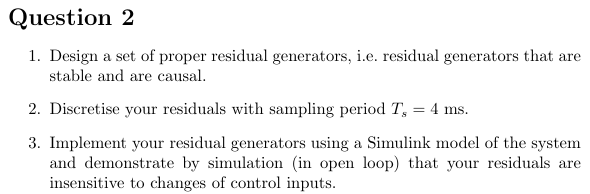

syms s Y3 Y2 Y1 U1 U2

r1 =  b3*diff(y3(t), t) - k2*(y2(t) - y3(t)) + J3*diff(y3(t), t, t);

r2 = (u2(t) - b2*diff(y2(t), t) + k1*y1(t) - k1*y2(t) - k2*y2(t) + k2*y3(t))/J2 - diff(y2(t), t, t);


lr1 =  b_3*s*Y3 - k_2*(Y2 - Y3) + J_3*s^2*Y3

lr2 = (U2 - b_2*s*Y2 + k_1*Y1 - k_1*Y2 - k_2*Y2 + k_2*Y3)/J_2 - s^2*Y2

lr3 = simplify(expand(-(s^2/k_2+1/J_2+k_1/(k_2*J_2)+b_2*s/(k_2*J_2))*lr1+lr2))


% List of residuals and inputs
residuals = [lr1; lr2; lr3];
inputs = [U1, U2, Y1, Y2, Y3];

H_tf = tf(zeros(3, 5));  % Preallocate a 4x5 tf matrix

% Populate the transfer function matrix with tf objects
for i = 1:3  % Loop over residuals (rows)
    for j = 1:5  % Loop over inputs (columns)
        % Substitute all other inputs with 0 to isolate the current input
        other_inputs = inputs;
        other_inputs(j) = [];  % Remove the current input
        temp_expr = vpa(subs(residuals(i), other_inputs, zeros(size(other_inputs))));
        
        if has(temp_expr, inputs(j))
            % Extract the coefficient (transfer function) of the current input
            coeff = simplify(temp_expr / inputs(j));
            
            % Convert symbolic expression to numerator and denominator polynomials
            [num_sym, den_sym] = numden(coeff);  % Get numerator and denominator
            num_coeffs = sym2poly(num_sym);      % Convert numerator to polynomial coefficients
            den_coeffs = sym2poly(den_sym);      % Convert denominator to polynomial coefficients
            
            % Assign the tf object directly to the matrix
            H_tf(i, j) = minreal(tf(num_coeffs, den_coeffs));
        else
            % If the input doesn't appear, assign a tf with 0 gain
            H_tf(i, j) = tf(0, 1);
        end
    end
end

% Display the transfer function matrix
disp('Transfer Function Matrix H(s) as a 3x5 tf object:');
disp(H_tf);

% Example: Access individual transfer functions
disp(H_tf(1,:));

Q_tf = tf(zeros(3,3))
Q_tf(1,1) = tf([1], [1 2 1])
Q_tf(2,2) = tf([1], [1 2 1])
Q_tf(3,3) = tf([1], [1 5 10 10 5 1])

R_M = Q_tf*H_tf


%pretty(R_M)

Ts = 0.004

DR_M = c2d(R_M,Ts,'zoh')


% Opgave 3

load('ECP502Data.mat');

[row, col] = size(y_meas);
T_sim = row*Ts;
arr = linspace(0, T_sim, row)';
y1_meas = [arr,y_meas(:,1)];
y2_meas = [arr,y_meas(:,2)];
y3_meas = [arr,y_meas(:,3)];
u_1t = [arr,u_1];
u_2t = [arr,u_2];

out = sim("simECP502Data.slx");
res = out.simout;
res = res.Data(2:end,:);

figure
grid on
hold off
subplot(3,1,1);
plot(arr,[u_1 u_2])
title("inputs")
legend('u1','u2');

subplot(3,1,2);
plot(arr,y_meas)
title("y_{meas}")
legend('y1','y2','y3');

subplot(3,1,3);
plot(arr,res())
title("residuals")
legend('y1','y2','y3');


figure
grid on
hold off
plot(arr,res(:,1))
title("residual 1")

figure
grid on
hold off
plot(arr,res(:,2))
title("residual 2")

figure
grid on
hold off
plot(arr,res(:,3))
title("residual 3")

%% State space representation
A = [ ];
B = [ ];
C = [  1 0 0 0 0 0
       0 0 1 0 0 0
       0 0 0 0 1 0 ];
D = [ ];
E_x = [ ];
E_y = [ ];
F_x = [ ];
F_y = [ ];
%%%%%%%% SKIP THAT WHEN SIMULATING IN OPEN LOOP %%%%%%%%%%%%%%%%%%%%%%%%%%%
% Discrete time
sys_d = [];
F_d = sys_d.A;

Dot indexing is not supported for variables of this type.

G_d = sys_d.B;

% State-feedback LQR design
Q_c = diag([2 0 2 0 2.5 0.0024]);
R_c = diag([10 10]);
K_c = [];

% Scaling of reference
C_ref = [];

% Kalman filter with friction estimation - DO NOT MODIFY
F_aug = [F_d G_d(:,1);zeros(1,6) 1];
G_aug = [G_d;0 0];
C_aug = [C zeros(3,1)];
% Kalman gain
L_aug = dlqe(F_aug,eye(7),C_aug,1e-3*eye(7),sigma_meas(1,1).^2*eye(3));
L_o = L_aug(1:6,:);
L_d = L_aug(7,:);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%% Residual filter design

%% Strong and weak detectability
H_rf = tf(0);

%% GLR
f_m = [0;-0.025;0];     % Sensor fault vector (added to [y1;y2;y3])
theta = 0;                  % Put the threshold from GLR here

%% Virtual actuator
% Failure in actuator 2
% Do the desing first in continuous time
va_eig_d = [];  % Discrete time eigenvalues
va_eig = log(va_eig_d)/T_s;     % Continuous time eigenvalues
% Then discretise your VA

B_change = [1 0;0 0];

%% Simulation for sensor fault (f_u = 0)
simTime = 45;                   % Simulation duration in seconds
f_u_time = 25;                  % Actuator fault occurence time
detect_time = f_u_time + 3.75;
f_u = [0;0];                    % Actuator fault vector (added to [u1;u2])
u_fault = 0;                    % Disable VA meachanism
f_m_time = 8.5;                 % Sensor fault occurence time
sim('threeDiskOscillatorRig');

%% Simulation for actuator fault (f_m = 0)
f_u = [0;-0.1];                 % Actuator fault vector (added to [u1;u2])
u_fault = 1;                    % Enable VA meachanism
f_m = [0;0;0];                  % Sensor fault vector (added to [y1;y2;y3])
sim('threeDiskOscillatorRig');

%% Plot settings
set(0,'DefaultTextInterpreter','latex');
set(0,'DefaultAxesFontSize',20);
set(0,'DefaultLineLineWidth', 2);